clear; clc;

% Punto 1
% Punto a) Cálculo de la pose del robot en cada paso

% Parámetros iniciales de la pose
posX = -1;               % Posición inicial en x (m)
posY = -5;               % Posición inicial en y (m)
orientacion = 0;         % Orientación inicial theta (rad)

% Comandos de velocidad del robot (lineal y angular)
velLineal = [1, 0, 1, 0, 1, 0, 1, 0, 1, 0, 1, 0];         % Velocidad lineal en m/s
velAngular = [0, pi/3, 0, pi/3, 0, pi/3, 0, pi/3, 0, pi/3, 0, pi/3]; % Velocidad angular en rad/s
tiempoPaso = ones(1, 12);   % Duración de cada paso (s)

% Inicialización de matriz para almacenar poses
trayectoria = zeros(12, 3); % Cada fila: [posX posY orientacion]

% Bucle de integración para calcular la nueva pose en cada paso
for paso = 1:12
    % Actualización de la pose utilizando cinemática diferencial
    posX = posX + velLineal(paso) * cos(orientacion) * tiempoPaso(paso);
    posY = posY + velLineal(paso) * sin(orientacion) * tiempoPaso(paso);
    orientacion = orientacion + velAngular(paso) * tiempoPaso(paso);

    % Guardar la pose actual
    trayectoria(paso, :) = [posX, posY, orientacion];
end

% Mostrar los resultados en forma de tabla
tablaResultados = table((1:12)', trayectoria(:,1), trayectoria(:,2), trayectoria(:,3), ...
    'VariableNames', {'Paso', 'X_m', 'Y_m', 'Theta_rad'});
disp(tablaResultados);

    Paso       X_m          Y_m      Theta_rad
    ____    __________    _______    _________

      1              0         -5          0  
      2              0         -5     1.0472  
      3            0.5     -4.134     1.0472  
      4            0.5     -4.134     2.0944  
      5     3.3307e-16    -3.2679     2.0944  
      6     3.3307e-16    -3.2679     3.1416  
      7             -1    -3.2679     3.1416  
      8             -1    -3.2679     4.1888  
      9           -1.5     -4.134     4.1888  
     10           -1.5     -4.134      5.236  
     11             -1         -5      5.236  
     12             -1         -5     6.2832  




% Punto b) Mostrar la pose final del robot
poseFinal = trayectoria(end, :); % Última pose (última fila de la matriz)

% Imprimir la pose final con formato
fprintf('\nPose final del robot tras 12 pasos:\n');


Pose final del robot tras 12 pasos:


fprintf('x = %.3f m\ny = %.3f m\ntheta = %.3f rad (%.2f°)\n', ...
    poseFinal(1), poseFinal(2), poseFinal(3), rad2deg(poseFinal(3)));

x = -1.000 m
y = -5.000 m
theta = 6.283 rad (360.00°)


clear; clc;

% Punto 2

% Parámetros físicos del robot diferencial
radioRueda = 0.1;    % Radio de la rueda en metros
distanciaEjes = 0.4; % Distancia entre ruedas (eje) en metros
pasoTiempo = 1.0;    % Intervalo de tiempo entre cada lectura (s)

% Lecturas de velocidades angulares (rad/s) de las ruedas derecha e izquierda
velAngDerecha = [4.582, 4.773, 5.291, 5.960, 6.490, ...
                -1.168, -1.364, 5.960, 5.291, 4.773, ...
                 4.582, 4.773, 5.291, 5.960, 6.490, ...
                 6.686, 6.490, 5.960, 5.291, 4.773, 4.582];

velAngIzquierda = [1.701, 2.353, 3.676, 4.856, 5.618, ...
                  13.735, 13.472, 4.856, 3.676, 2.353, ...
                   1.701, 2.353, 3.676, 4.856, 5.618, ...
                   5.881, 5.618, 4.856, 3.676, 2.353, 1.701];

numPasos = length(velAngDerecha);  % Total de pasos de simulación

% Inicialización de arreglos para almacenar resultados
velLineal = zeros(1, numPasos);            % Velocidad lineal del robot
velAngular = zeros(1, numPasos);           % Velocidad angular del robot
posX = zeros(1, numPasos + 1);             % Posición en x
posY = zeros(1, numPasos + 1);             % Posición en y
orientacion = zeros(1, numPasos + 1);      % Orientación (theta) en radianes

% Condición inicial del robot
posX(1) = 0; 
posY(1) = 0; 
orientacion(1) = 0;

% Cálculo de la trayectoria paso a paso
for paso = 1:numPasos
    % Calcular velocidad lineal y angular a partir de omegas
    velLineal(paso) = (radioRueda / 2) * (velAngDerecha(paso) + velAngIzquierda(paso));
    velAngular(paso) = (radioRueda / distanciaEjes) * (velAngDerecha(paso) - velAngIzquierda(paso));

    % Actualizar orientación (theta)
    orientacion(paso + 1) = orientacion(paso) + velAngular(paso) * pasoTiempo;

    % Calcular nueva posición (usando theta actualizado)
    posX(paso + 1) = posX(paso) + velLineal(paso) * cos(orientacion(paso + 1)) * pasoTiempo;
    posY(paso + 1) = posY(paso) + velLineal(paso) * sin(orientacion(paso + 1)) * pasoTiempo;
end

% Extensión de vectores para generar la tabla (NaN para última fila)
velLineal_ext = [velLineal, NaN];
velAngular_ext = [velAngular, NaN];
velAngDerecha_ext = [velAngDerecha, NaN];
velAngIzquierda_ext = [velAngIzquierda, NaN];
posX_ext = posX';
posY_ext = posY';
orientacion_deg = rad2deg(orientacion');

% Crear tabla con los resultados completos
tablaPaso2 = table((0:numPasos)', ...
    velLineal_ext', ...
    velAngular_ext', ...
    velAngDerecha_ext', ...
    velAngIzquierda_ext', ...
    posX_ext, posY_ext, orientacion_deg, ...
    'VariableNames', {'t_s', 'v_mps', 'w_rps', 'omega_R', 'omega_L', 'x_m', 'y_m', 'theta_deg'});

% Mostrar la tabla en consola
disp(tablaPaso2);

    t_s     v_mps      w_rps     omega_R    omega_L       x_m         y_m        theta_deg 
    ___    _______    _______    _______    _______    _________    ________    ___________

     0     0.31415    0.72025     4.582      1.701             0           0              0
     1      0.3563      0.605     4.773      2.353       0.23613      0.2072         41.267
     2     0.44835    0.40375     5.291      3.676       0.32274     0.55282         75.931
     3      0.5408      0.276      5.96      4.856        0.2521     0.99557         99.064
     4      0.6054      0.218      6.49      5.618      0.024596      1.4862         114.88
     5     0.62835    -3.7257    -1.168     13.735      -0.34284      1.9673       

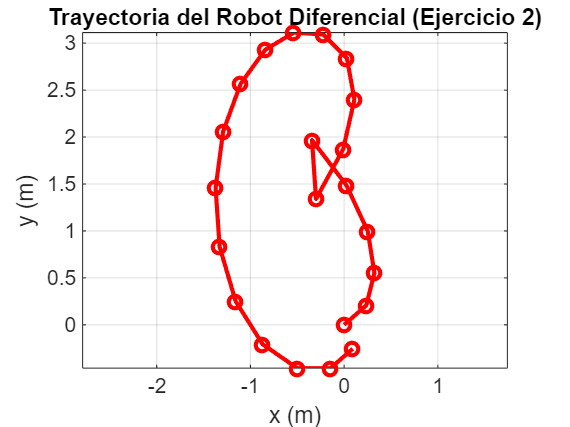


% Graficar la trayectoria recorrida por el robot
figure;
plot(posX, posY, 'r-o', 'LineWidth', 2);
xlabel('x (m)');
ylabel('y (m)');
title('Trayectoria del Robot Diferencial (Ejercicio 2)');
grid on;
axis equal;

clear; clc;

% Punto 3 - Simulación de trayectoria circular para robot diferencial

% Parámetros físicos del robot
radioRueda = 0.1;       % Radio de las ruedas (m)
distanciaRuedas = 0.4;  % Distancia entre ruedas (m)
intervaloTiempo = 1.0;  % Tiempo entre pasos de simulación (s)

% Parámetros de trayectoria deseada
radioTrayectoria = 20;  % Radio de la trayectoria circular (m)
velocidadLineal = 1.0;  % Velocidad constante del robot (m/s)

% Cálculo de velocidad angular deseada
velocidadAngular = velocidadLineal / radioTrayectoria;

% Cálculo de velocidades angulares de las ruedas
omegaDerecha = (2 * velocidadLineal + velocidadAngular * distanciaRuedas) / (2 * radioRueda);
omegaIzquierda = (2 * velocidadLineal - velocidadAngular * distanciaRuedas) / (2 * radioRueda);

% Número total de pasos de simulación
totalPasos = 126;

% Inicialización de vectores de trayectoria y velocidades
posX = zeros(1, totalPasos + 1);
posY = zeros(1, totalPasos + 1);
orientacion = zeros(1, totalPasos + 1);  % Ángulo theta (rad)
velLineal = zeros(1, totalPasos);
velAngular = zeros(1, totalPasos);
omegaDerechaArray = omegaDerecha * ones(1, totalPasos);
omegaIzquierdaArray = omegaIzquierda * ones(1, totalPasos);

% Bucle de simulación paso a paso
for paso = 1:totalPasos
    velLineal(paso) = (radioRueda / 2) * (omegaDerecha + omegaIzquierda);
    velAngular(paso) = (radioRueda / distanciaRuedas) * (omegaDerecha - omegaIzquierda);

    % Actualizar orientación
    orientacion(paso + 1) = orientacion(paso) + velAngular(paso) * intervaloTiempo;

    % Actualizar posición (usando orientación actualizada)
    posX(paso + 1) = posX(paso) + velLineal(paso) * cos(orientacion(paso + 1)) * intervaloTiempo;
    posY(paso + 1) = posY(paso) + velLineal(paso) * sin(orientacion(paso + 1)) * intervaloTiempo;
end

% Crear tabla de resultados para análisis
tablaCircular = table((0:totalPasos - 1)', ...
    velLineal', velAngular', ...
    omegaDerechaArray', omegaIzquierdaArray', ...
    posX(1:end - 1)', posY(1:end - 1)', rad2deg(orientacion(1:end - 1))', ...
    'VariableNames', {'t_s', 'v_mps', 'w_rps', ...
                      'omega_R', 'omega_L', ...
                      'x_m', 'y_m', 'theta_deg'});

% Mostrar la tabla en consola
disp(tablaCircular);

    t_s    v_mps    w_rps    omega_R    omega_L      x_m          y_m        theta_deg
    ___    _____    _____    _______    _______    ________    __________    _________

      0      1      0.05      10.1        9.9             0             0          0  
      1      1      0.05      10.1        9.9       0.99875      0.049979     2.8648  
      2      1      0.05      10.1        9.9        1.9938       0.14981     5.7296  
      3      1      0.05      10.1        9.9        2.9825       0.29925     8.5944  
      4      1      0.05      10.1        9.9        3.9626       0.49792     11.459  
      5      1      0.05      10.1        9.9        4.9315       0.74532     14.324  
      6      1      0.05      1

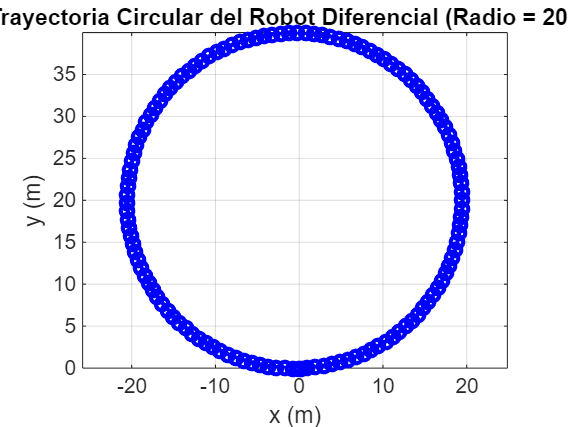


% Graficar la trayectoria circular generada
figure;
plot(posX, posY, 'b-o', 'LineWidth', 2);
xlabel('x (m)');
ylabel('y (m)');
title('Trayectoria Circular del Robot Diferencial (Radio = 20 m)');
grid on;
axis equal;